clear
theta = 90*pi/(180)

theta = 1.5708

x0 =0 ; y0 =0;
r0 = 0; rf = 10;
v0 = 0; vf = 0;
t0 = 0; tf = 5;

t = linspace(t0,tf,100*(tf-t0))

t =          0    0.0100    0.0200    0.0301    0.0401    0.0501    0.0601    0.0701    0.0802    0.0902    0.1002    0.1102    0.1202    0.1303    0.1403    0.1503    0.1603    0.1703    0.1804    0.1904    0.2004    0.2104    0.2204    0.2305    0.2405    0.2505    0.2605    0.2705    0.2806    0.2906    0.3006    0.3106    0.3206    0.3307    0.3407    0.3507    0.3607    0.3707    0.3808    0.3908    0.4008    0.4108    0.4208    0.4309    0.4409    0.4509    0.4609    0.4709    0.4810    0.4910


c0 = 0; c1 =0;
c2 =(3*rf)/tf^2;
c3 =(-2*rf)/tf^3;
rt = c0 + c1*t + c2*t.^2 + c3*t.^3;
vt = c1 + 2*c2*t + 3*c3*t.^2;
x = x0 + (rt*cos(theta))

x = 	1.0e+-15 *

         0    0.0000    0.0000    0.0001    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0012    0.0014    0.0016    0.0018    0.0021    0.0023    0.0026    0.0029    0.0032    0.0035    0.0038    0.0041    0.0045    0.0048    0.0052    0.0056    0.0060    0.0064    0.0068    0.0072    0.0077    0.0081    0.0086    0.0091    0.0096    0.0101    0.0106    0.0112    0.0117    0.0123    0.0129    0.0134    0.0140    0.0147    0.0153    0.0159    0.0166


y = y0 + (rt*sin(theta))

y =          0    0.0001    0.0005    0.0011    0.0019    0.0030    0.0043    0.0058    0.0076    0.0096    0.0119    0.0144    0.0171    0.0200    0.0232    0.0266    0.0302    0.0340    0.0381    0.0424    0.0469    0.0516    0.0566    0.0618    0.0672    0.0728    0.0786    0.0847    0.0909    0.0974    0.1041    0.1110    0.1181    0.1254    0.1330    0.1407    0.1486    0.1568    0.1651    0.1737    0.1825    0.1914    0.2006    0.2100    0.2195    0.2293    0.2393    0.2494    0.2598    0.2703


vx = vt*cos(theta)

vx = 	1.0e+-15 *

         0    0.0015    0.0029    0.0044    0.0058    0.0073    0.0087    0.0102    0.0116    0.0130    0.0144    0.0158    0.0172    0.0186    0.0200    0.0214    0.0228    0.0242    0.0255    0.0269    0.0283    0.0296    0.0310    0.0323    0.0336    0.0350    0.0363    0.0376    0.0389    0.0402    0.0415    0.0428    0.0441    0.0454    0.0467    0.0479    0.0492    0.0504    0.0517    0.0529    0.0542    0.0554    0.0566    0.0579    0.0591    0.0603    0.0615    0.0627    0.0639    0.0651


vy = vt*sin(theta)

vy =          0    0.0240    0.0479    0.0717    0.0954    0.1190    0.1426    0.1660    0.1893    0.2125    0.2357    0.2587    0.2816    0.3045    0.3272    0.3499    0.3724    0.3949    0.4173    0.4395    0.4617    0.4838    0.5057    0.5276    0.5494    0.5711    0.5927    0.6142    0.6356    0.6569    0.6781    0.6992    0.7202    0.7411    0.7619    0.7826    0.8033    0.8238    0.8442    0.8646    0.8848    0.9050    0.9250    0.9450    0.9648    0.9846    1.0042    1.0238    1.0433    1.0626


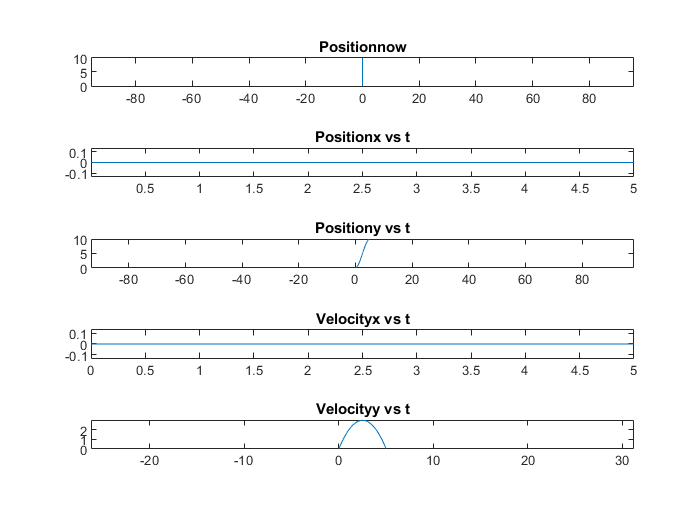

% plot
subplot(511)
plot(x,y)
axis equal
title('Positionnow')
subplot(512)
plot(t,x)
axis equal
title('Positionx vs t')
subplot(513)
plot(t,y)
axis equal
title('Positiony vs t')
subplot(514)
plot(t,vx)
axis equal
title('Velocityx vs t')
subplot(515)
plot(t,vy)
title('Velocityy vs t')
axis equal